## AAE334L Lab4 Postlab MATLAB CODE

clear all; close all; clc;

fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE334LAB\matlab\outputs\lab4';
set(groot, 'defaulttextinterpreter',"latex");
set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter',"latex");

### SETUP

% Defining necessary constants
gamma = 1.4;

% Defining the vector with the pressure tap locations 
p_tap = inch2m([14 13 12 11 10 9 7 6 5 4 1 0 -0.5 -1.5]);

% Reference pressures
P_ref_40 = psi2Pa(40);  % 40 psi [Pa]
P_ref_45 = psi2Pa(45);  % 45 psi [Pa]
P_ref_50 = psi2Pa(50);  % 50 psi [Pa]
P_ref_55 = psi2Pa(55);  % 55 psi [Pa]
P_ref_60 = psi2Pa(60);  % 60 psi [Pa]

% Importing data 
% Small wedge
data_SW = readmatrix("inputs\lab4\small_wedge.xlsx");
data_SW = psi2Pa(data_SW);  % converting units from psi to Pa
% Diamond 
data_DM = readmatrix("inputs\lab4\diamond.xlsx");
data_DM = psi2Pa(data_DM);  % converting units from psi to Pa
% Blunt body
data_BB = readmatrix("inputs\lab4\blunt_body.xlsx");
data_BB = psi2Pa(data_BB);  % converting units from psi to Pa

% Assigning variables for the acquired pressure data
% Small wedge
% 45 psi
P_SW_45  = P_ref_45 + mean(data_SW(1:7,2:15));
% 50 psi
P_SW_50  = P_ref_50 + mean(data_SW(9:18,2:15));
% 55 psi
P_SW_55  = P_ref_55 + mean(data_SW(20:32,2:15));
% 60 psi
P_SW_60  = P_ref_60 + mean(data_SW(34:46,2:15));

% Diamond
% 40 psi
P_DM_40  = P_ref_40 + mean(data_DM(1:12,2:15));
% 45 psi
P_DM_45  = P_ref_45 + mean(data_DM(14:24,2:15));
% 50 psi
P_DM_50  = P_ref_50 + mean(data_DM(26:34,2:15));
% 55 psi
P_DM_55  = P_ref_55 + mean(data_DM(36:45,2:15));

% Blunt body
% 45 psi
P_BB_45  = P_ref_45 + mean(data_BB(1:8,2:15));
% 50 psi
P_BB_50  = P_ref_50 + mean(data_BB(10:21,2:15));
% 55 psi
P_BB_55  = P_ref_55 + mean(data_BB(23:34,2:15));

### 1-a

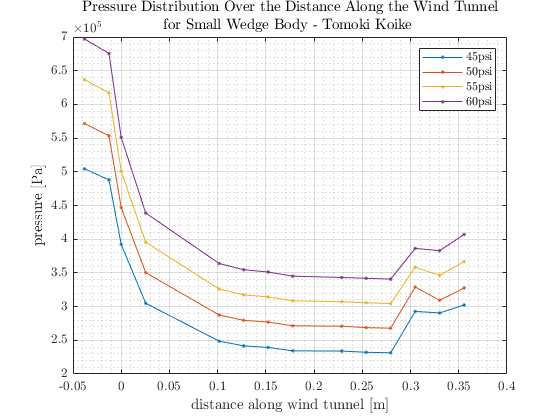

% Plotting the pressure over the location of the pressure tap 
% Small wedge
fig1 = figure("Renderer","painters");
    plot(p_tap,P_SW_45,'.-')
    title({'Pressure Distribution Over the Distance Along the Wind Tunnel', ['' ...
        'for Small Wedge Body - Tomoki Koike ']})
    xlabel('distance along wind tunnel [m]')
    ylabel('pressure [Pa]')
    hold on 
    plot(p_tap,P_SW_50,'.-')
    plot(p_tap,P_SW_55,'.-')
    plot(p_tap,P_SW_60,'.-')
    hold off
    grid on; grid minor; box on;
    legend('45psi','50psi','55psi','60psi')
saveas(fig1, fullfile(fdir,'p_dist_SW.png'))

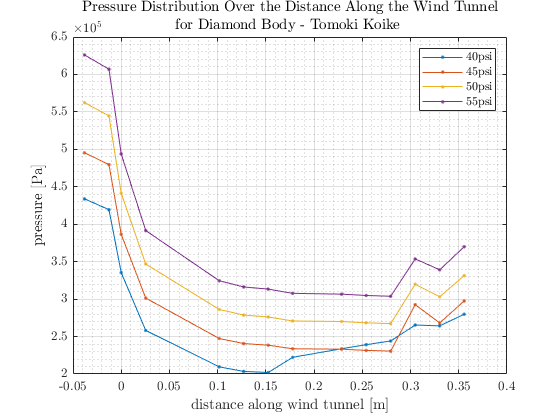


% Diamond
fig2 = figure("Renderer","painters");
    plot(p_tap,P_DM_40,'.-')
    title({'Pressure Distribution Over the Distance Along the Wind Tunnel', ['' ...
        'for Diamond Body - Tomoki Koike ']})
    xlabel('distance along wind tunnel [m]')
    ylabel('pressure [Pa]')
    hold on 
    plot(p_tap,P_DM_45,'.-')
    plot(p_tap,P_DM_50,'.-')
    plot(p_tap,P_DM_55,'.-')
    hold off
    grid on; grid minor; box on;
    legend('40psi','45psi','50psi','55psi')
saveas(fig2, fullfile(fdir,'p_dist_DM.png'))

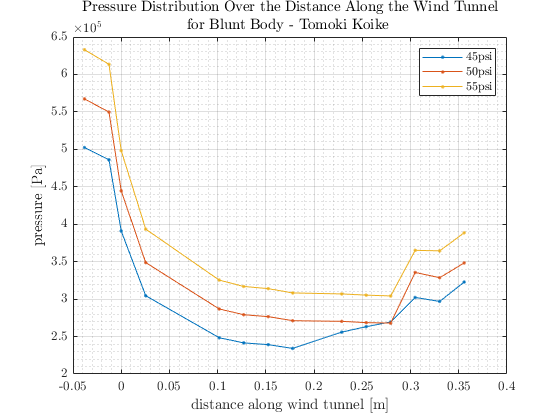


% Blunt body
fig3 = figure("Renderer","painters");
    plot(p_tap,P_BB_45,'.-')
    title({'Pressure Distribution Over the Distance Along the Wind Tunnel', ['' ...
        'for Blunt Body - Tomoki Koike ']})
    xlabel('distance along wind tunnel [m]')
    ylabel('pressure [Pa]')
    hold on 
    plot(p_tap,P_BB_50,'.-')
    plot(p_tap,P_BB_55,'.-')
    hold off
    grid on; grid minor; box on;
    legend('45psi','50psi','55psi')
saveas(fig3, fullfile(fdir,'p_dist_BB.png'))

### 1-b

% Calculating the Mach numbers 
% Small wedge
M_SW_45 = MachNum_from_p(P_SW_45(14),P_SW_45(1:14));
M_SW_50 = MachNum_from_p(P_SW_50(14),P_SW_50(1:14));
M_SW_55 = MachNum_from_p(P_SW_55(14),P_SW_55(1:14));
M_SW_60 = MachNum_from_p(P_SW_60(14),P_SW_60(1:14));

% Diamond 
M_DM_40 = MachNum_from_p(P_DM_40(14),P_DM_40(1:14));
M_DM_45 = MachNum_from_p(P_DM_45(14),P_DM_45(1:14));
M_DM_50 = MachNum_from_p(P_DM_50(14),P_DM_50(1:14));
M_DM_55 = MachNum_from_p(P_DM_55(14),P_DM_55(1:14));

% Blunt body
M_BB_45 = MachNum_from_p(P_BB_45(14),P_BB_45(1:14));
M_BB_50 = MachNum_from_p(P_BB_50(14),P_BB_50(1:14));
M_BB_55 = MachNum_from_p(P_BB_55(14),P_BB_55(1:14));

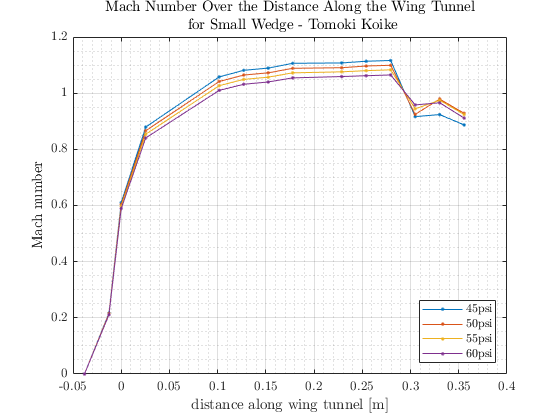

% Plotting
fig4 = figure("Renderer","painters");
    plot(p_tap, M_SW_45,'.-')
    title({'Mach Number Over the Distance Along the Wing Tunnel',[' for Small' ...
        ' Wedge - Tomoki Koike']})
    xlabel('distance along wing tunnel [m]')
    ylabel('Mach number')
    hold on
    plot(p_tap,M_SW_50,'.-')
    plot(p_tap,M_SW_55,'.-')
    plot(p_tap,M_SW_60,'.-')
    hold off
    grid on; grid minor; box on;
    legend('45psi','50psi','55psi','60psi','Location','southeast')
saveas(fig4, fullfile(fdir,'Mach_SW.png'))

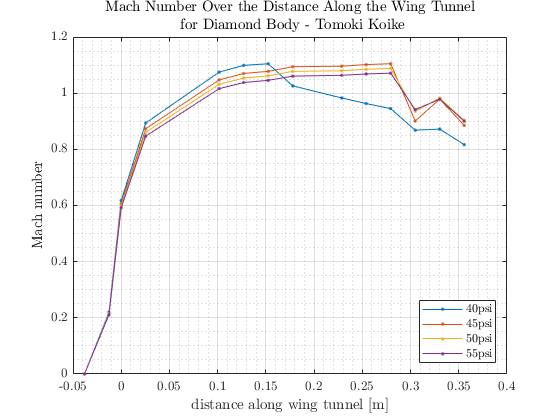


fig5 = figure("Renderer","painters");
    plot(p_tap, M_DM_40,'.-')
    title({'Mach Number Over the Distance Along the Wing Tunnel',[' for Diamond' ...
        ' Body - Tomoki Koike']})
    xlabel('distance along wing tunnel [m]')
    ylabel('Mach number')
    hold on
    plot(p_tap,M_DM_45,'.-')
    plot(p_tap,M_DM_50,'.-')
    plot(p_tap,M_DM_55,'.-')
    hold off
    grid on; grid minor; box on;
    legend('40psi','45psi','50psi','55psi','Location','southeast')
saveas(fig5, fullfile(fdir,'Mach_DM.png'))

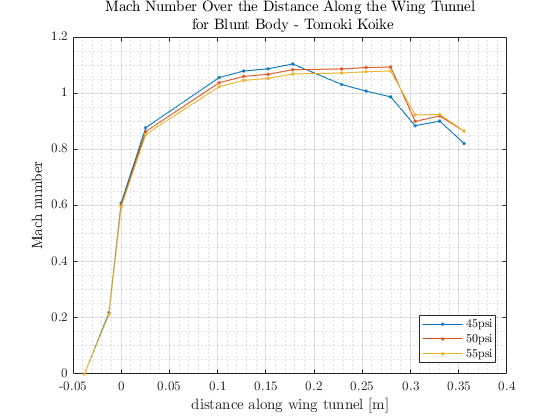


fig6 = figure("Renderer","painters");
    plot(p_tap, M_BB_45,'.-')
    title({'Mach Number Over the Distance Along the Wing Tunnel',[' for Blunt' ...
        ' Body - Tomoki Koike']})
    xlabel('distance along wing tunnel [m]')
    ylabel('Mach number')
    hold on
    plot(p_tap,M_BB_50,'.-')
    plot(p_tap,M_BB_55,'.-')
    hold off
    grid on; grid minor; box on;
    legend('45psi','50psi','55psi','Location','southeast')
saveas(fig6, fullfile(fdir,'Mach_BB.png'))

### 2-a

% Calculating the theoretical shockwave angle numerically
syms beta 
theta = 0.1396;  % half angle of wedge [rad]
M1 = M_DM_55(12);  % Mach number after shockwave for dimaond @ 
a1 = (gamma + 1)*M1^2/(2*(M1^2*(sin(beta))^2 - 1));
eqn = cot(theta) == tan(beta)*(a1 - 1);
res = solve(eqn,beta)

$$res = -\log\left(\mathrm{root}\left(z^{6}+z^{4}\,\left(\frac{618066975112118686036843627281949507803632983841}{59095811233098557553098186603368237360079347935}-\frac{53201000427109125171934271799453767170049179648}{137890226210563300957229102074525887173518478515}\,\mathrm{i}\right)+z^{2}\,\left(\frac{4114947111362010218936402904190506135282426157543}{413670678631689902871687306223577661520555435545}+\frac{448579967997708653930578457322234439000840470528}{137890226210563300957229102074525887173518478515}\,\mathrm{i}\right)+\frac{62936119478681459727296965840793}{65471420679137918530290372251545}+\frac{18043053807761601062654888116224}{65471420679137918530290372251545}\,\mathrm{i},z,1\right)\right)\,\mathrm{i}$$

res = double(solve(eqn,beta))

res = -1.6137 + 1.1250i

beta = rad2deg(angle(res))

beta = 145.1159


% percent error 
err = abs(37.3210 - 38.8841)/38.8841 * 100

err = 4.0199

### FUNCTIONS 

function M = MachNum_from_p(P0,Pi)
    %{
      inputs:  (1) Pi: pressure for the static pressures
                       (vector or scalar input)
      outputs: (1) M:  mach number for isentropic relations (vector
                       or scalar)
    %}
    
    gamma = 1.4;  % constant of heat capacity ratio
    % Calculating the mach number
    a1 = 2/(gamma - 1);
    a2 = (gamma - 1)/gamma;
    a3 = (P0./Pi).^a2 - 1;
    M = sqrt(a1.*a3);
end